clf
clear
clc
close all 
set(groot, 'DefaultFigureColor', 'w');
 R = 8.314; % J/mol/K
 %TEMPERATURE AT 250 C
T = 250 + 273.15;
    % --- Activation Energy parameters (converted kJ/mol -> J/mol) --- %
    A_kCH3OH = 1.50e7;   Ea_kCH3OH = 86.00e3;
    A_KCH3OH = 2.60e-4;  Ea_KCH3OH = -56.78e3;
    A_KO2    = 1.42e-5;  Ea_KO2    = -60.32e3;
    A_KH2O   = 5.50e-7;  Ea_KH2O   = -86.45e3;
    A_kCO    = 3.50e2;   Ea_kCO    = 46.00e3;
    
    % --- Calculation of rate constants from params --- %
    kCH3OH = A_kCH3OH * exp(-Ea_kCH3OH/(R*T));
    KCH3OH = A_KCH3OH * exp(-Ea_KCH3OH/(R*T));
    KO2    = A_KO2    * exp(-Ea_KO2/(R*T));
    KH2O   = A_KH2O   * exp(-Ea_KH2O/(R*T));
    kCO    = A_kCO    * exp(-Ea_kCO/(R*T));

    alpha = 0.44;

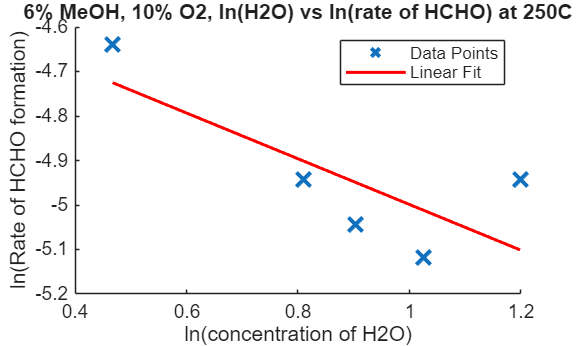

%---------1st reaction----------

%data set a1: H2O inlet concentration vs Rate of HCHO formation
%rate with constant MeOH(6%), oxygen(10%) 
%250C 
% rate order of H2O will be determined here
H2O_a1_250 = [1.5961    2.2488    2.4685    2.7851    3.3150];
R_HCHO_a1_250 = 10^-3.*[9.6658    7.1342    6.4438    5.9836    7.1342];

ln_H2O_a1_250 = log(H2O_a1_250);
ln_R_HCHO_a1_250 = log(R_HCHO_a1_250);

figure ("Name","Reaction Order of H2O (250C)")
scatter(ln_H2O_a1_250,ln_R_HCHO_a1_250,'x','SizeData',100,'Linewidth',2);
xlabel("ln(concentration of H2O)")
ylabel("ln(Rate of HCHO formation)")
hold on
H2O_Trendline = polyfit(ln_H2O_a1_250,ln_R_HCHO_a1_250,1);
y_values_H2O = polyval(H2O_Trendline , ln_H2O_a1_250);
plot(ln_H2O_a1_250, y_values_H2O, 'r-','LineWidth',1.5);
legend('Data Points', 'Linear Fit');
title("6% MeOH, 10% O2, ln(H2O) vs ln(rate of HCHO) at 250C")
hold off

%R^2 value 
mdl = fitlm(y_values_H2O,ln_R_HCHO_a1_250);           % X predictors, y response
rxn1_a1_250_rsquared = mdl.Rsquared.Ordinary

rxn1_a1_250_rsquared = 0.5899

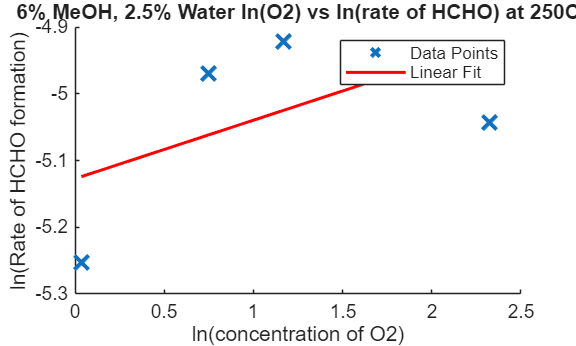

%data set a2: O2 inlet concentration vs Rate of HCHO formation
%rate with constant MeOH(6%), water(2.5%) 
%250C 
% rate order of O2 will be determined here

O2_a2_250 = [1.0363    2.1111    3.2218    5.1195    7.0852   10.2314];
R_HCHO_a2_250 = 10^-3.*[5.2358    6.9431    7.2846    7.0569    7.2087    6.4499];

ln_O2_a2_250 = log(O2_a2_250);
ln_R_HCHO_a2_250 = log(R_HCHO_a2_250);

figure ("Name","Reaction Order of O2 (250C)")
scatter(ln_O2_a2_250,ln_R_HCHO_a2_250,'x','SizeData',100,'Linewidth',2);
xlabel("ln(concentration of O2)")
ylabel("ln(Rate of HCHO formation)")
hold on
O2_Trendline = polyfit(ln_O2_a2_250,ln_R_HCHO_a2_250,1);
y_values_O2 = polyval(O2_Trendline , ln_O2_a2_250);
plot(ln_O2_a2_250, y_values_O2, 'r-','LineWidth',1.5);
legend('Data Points', 'Linear Fit');
title("6% MeOH, 2.5% Water ln(O2) vs ln(rate of HCHO) at 250C")
hold off

%R^2 value 
mdl = fitlm(y_values_O2,ln_R_HCHO_a2_250);           % X predictors, y response
rxn1_a2_250_rsquared = mdl.Rsquared.Ordinary

rxn1_a2_250_rsquared = 0.3448

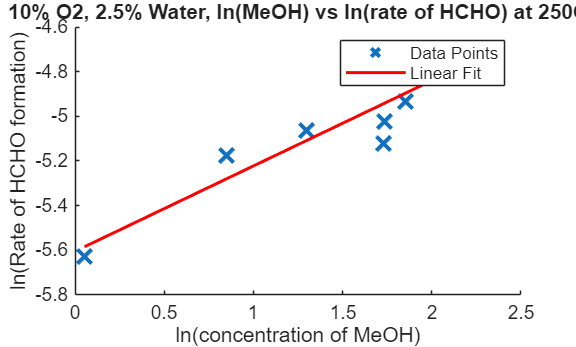

%data set a3: MeOH inlet concentration vs Rate of HCHO formation
%rate with constant O2(10%), water(2.5%) 
%250C 
% rate order of MeOH will be determined here

MeOH_a3_250 = [1.0554    2.3443    3.6676    5.6237    5.6607    6.3680    6.9861    7.8738    9.6124];
R_HCHO_a3_250 = 10^-3.*[3.5956    5.6612    6.3115    5.9672    6.5792    7.1913    8.8743    8.8743    8.4536];

ln_MeOH_a3_250 = log(MeOH_a3_250);
ln_R_HCHO_a3_250 = log(R_HCHO_a3_250);

figure ("Name","Reaction Order of MeOH (250C)")
scatter(ln_MeOH_a3_250,ln_R_HCHO_a3_250,'x','SizeData',100,'Linewidth',2);
xlabel("ln(concentration of MeOH)")
ylabel("ln(Rate of HCHO formation)")
hold on
MeOH_Trendline = polyfit(ln_MeOH_a3_250,ln_R_HCHO_a3_250,1);
y_values_MeOH = polyval(MeOH_Trendline , ln_MeOH_a3_250);
plot(ln_MeOH_a3_250, y_values_MeOH, 'r-','LineWidth',1.5);
legend('Data Points', 'Linear Fit');
title("10% O2, 2.5% Water, ln(MeOH) vs ln(rate of HCHO) at 250C")
hold off

%R^2 value 
mdl = fitlm(y_values_MeOH,ln_R_HCHO_a3_250);           % X predictors, y response
rxn1_a3_250_rsquared = mdl.Rsquared.Ordinary

rxn1_a3_250_rsquared = 0.8729

% displaying rate orders and rate equation
rxn1_H2O_order_250 = H2O_Trendline(1)

rxn1_H2O_order_250 = -0.5141

rxn1_O2_order_250 = O2_Trendline(1)

rxn1_O2_order_250 = 0.0876

rxn1_MeOH_order_250 = MeOH_Trendline(1)

rxn1_MeOH_order_250 = 0.3825


%k calculation at 250C
%using dataset a1

CH3OH_250 = [6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    1.0554    2.3443    3.6676    5.6237    5.6607    6.3680    6.9861    7.8738    9.6124    6.0000    6.0000    6.0000    6.0000    6.0000];
O2_250 = [1.0363    2.1111    3.2218    5.1195    7.0852   10.2314   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000];
H2O_250 = [2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    2.5000    1.5961    2.2488    2.4685    2.7851    3.3150];
rate_250 = 10^-3.*[5.2358    6.9431    7.2846    7.0569    7.2087    6.4499    3.5956    5.6612    6.3115    5.9672    6.5792    7.1913    8.8743    8.8743    8.4536    9.6658    7.1342    6.4438    5.9836    7.1342];

k = rate_250./(CH3OH_250.^(rxn1_MeOH_order_250).*O2_250.^(rxn1_O2_order_250).*H2O_250.^(rxn1_H2O_order_250));
k1_250 = mean(k);
fprintf('k1 = %.8f\n',k1_250 )

k1 = 0.00478735


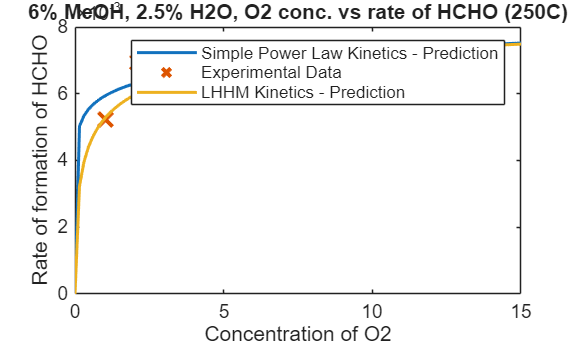

%using rate equation to plot
%plotting for O2 vs R(HCHO) at 250C
figure("Name","Concentration of O2 vs Rate of HCHO")
o2_conc = linspace(0,15,100);

R_HCHO_predicted_a2 = k1_250.*(6.^rxn1_MeOH_order_250).*(o2_conc.^rxn1_O2_order_250).*(2.5.^rxn1_H2O_order_250);
plot(o2_conc,R_HCHO_predicted_a2,'LineWidth',1.5)
hold on
%experimental data
scatter(O2_a2_250,R_HCHO_a2_250,'x','SizeData',100,'Linewidth',2);

%LHHW model
nom1 = alpha*kCH3OH*KCH3OH*(6/100)*KO2.*((o2_conc./100).^0.5);
den1 = (1+KCH3OH*(6/100)+KH2O*(2.5/100)).*(1+KO2.*(o2_conc./100).^0.5);
R_HCHO_LHHW_a2 = nom1./den1;

plot(o2_conc,R_HCHO_LHHW_a2,'LineWidth',1.5)
legend(["Simple Power Law Kinetics - Prediction","Experimental Data","LHHM Kinetics - Prediction"])
xlabel("Concentration of O2")
ylabel("Rate of formation of HCHO")
title("6% MeOH, 2.5% H2O, O2 conc. vs rate of HCHO (250C)")

hold off

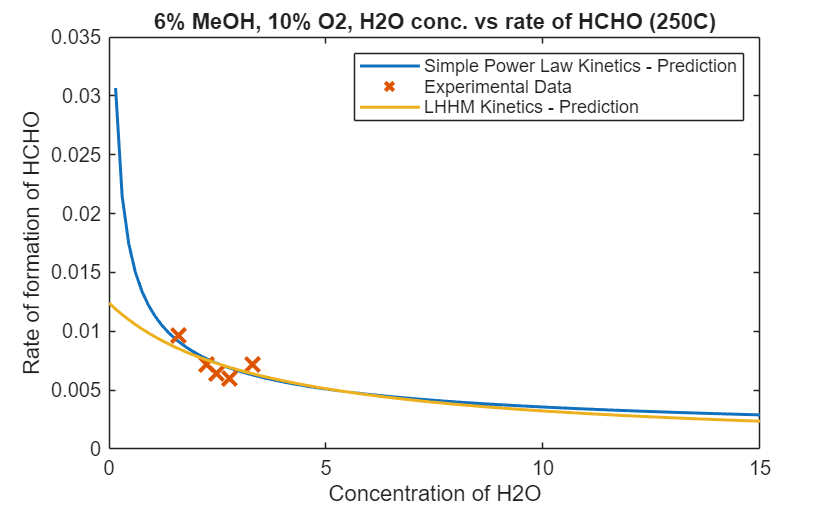

%plotting for H2O vs R(HCHO) at 250C
% 6% methanol and 10% oxygen
figure("Name","Concentration of H2O vs Rate of HCHO)")
H2O_conc = linspace(0,15,100);

R_HCHO_predicted_a1 = k1_250.*(6.^rxn1_MeOH_order_250).*(10.^rxn1_O2_order_250).*(H2O_conc.^rxn1_H2O_order_250);
plot(H2O_conc,R_HCHO_predicted_a1,"LineWidth",1.5)
hold on 
%experimental data 
scatter(H2O_a1_250,R_HCHO_a1_250,'x','SizeData',100,'linewidth',2);

%LHHW Model
nom2 = alpha*kCH3OH*KCH3OH*(6/100)*KO2.*((10/100).^0.5);
den2 = (1+KCH3OH*(6/100)+KH2O*(H2O_conc./100)).*(1+KO2.*(10/100).^0.5);
R_HCHO_LHHW_a1 = nom2./den2;

plot(H2O_conc,R_HCHO_LHHW_a1,'LineWidth',1.5)
legend(["Simple Power Law Kinetics - Prediction","Experimental Data","LHHM Kinetics - Prediction"])
xlabel("Concentration of H2O")
ylabel("Rate of formation of HCHO")
title("6% MeOH, 10% O2, H2O conc. vs rate of HCHO (250C)")
hold off

%plotting for CH3OH vs R(HCHO) at 250C
% 10% oxygen and 2.5% H2O
figure("Name","Concentration of CH3OH vs Rate of HCHO)")
MeOH_conc = linspace(0,15,100);

R_HCHO_predicted_a3 = k1_250.*(CH3OH_conc.^rxn1_MeOH_order_250).*(10.^rxn1_O2_order_250).*(H2O_conc.^rxn1_H2O_order_250);


% to do: other graphs at 250C, rate order calculation at 270C, graphs
% plotting at 270C